% load experiment and replace units with new sorting
experiment.Units = sorted_from_phy('/lampllab/Data/Awake_AP2.5_ML4.0_A1/FVB/301121/986/kilosort/');
experiment.evokedEvents = experiment.getEvoked

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB108_986'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: []
            evokedEvents: [1×1 struct]
         conditionVector: []


% Find whisking epochs
[b,a] = butter(2,[0.1,150]/200,'bandpass');
mot_filt = filtfilt(b,a,double(motion_1))

mot_filt = 1.0e+04 *

    0.0553    0.0699    0.1138    0.0834    0.0848    0.0938    0.0939    0.1148    0.0413    0.0045   -0.0241   -0.0405    0.0901    0.1061    0.0519   -0.0466   -0.2161   -0.2048   -0.1841   -0.1853   -0.1449   -0.0981    0.1114    0.1530   -0.0573   -0.0590   -0.0042    0.0725    0.2810    0.1016   -0.2090   -0.0454    0.0261   -0.2098   -0.2264   -0.1105    0.0302    0.2144    0.2185    0.1454    0.1003    0.0325    0.0147    0.0835    0.0870   -0.0456    0.0229    0.1861    0.1027    0.0438


mot_filt = mot_filt/mean(mot_filt)

mot_filt = 1.0e+05 *

    0.0265    0.0335    0.0546    0.0400    0.0407    0.0450    0.0450    0.0551    0.0198    0.0022   -0.0116   -0.0194    0.0432    0.0509    0.0249   -0.0224   -0.1036   -0.0982   -0.0883   -0.0889   -0.0695   -0.0471    0.0534    0.0734   -0.0275   -0.0283   -0.0020    0.0348    0.1347    0.0487   -0.1002   -0.0218    0.0125   -0.1006   -0.1085   -0.0530    0.0145    0.1028    0.1048    0.0697    0.0481    0.0156    0.0071    0.0401    0.0417   -0.0219    0.0110    0.0893    0.0493    0.0210


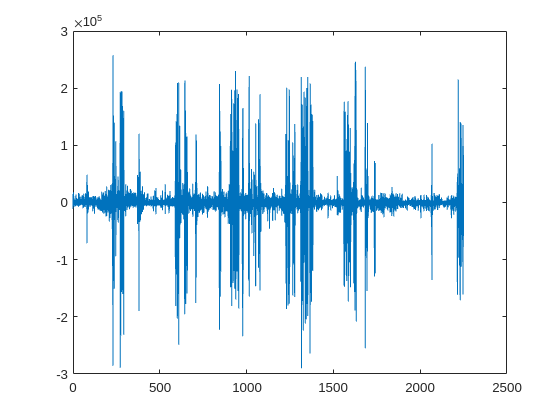

figure; plot([1:length(mot_filt)]/400,(mot_filt))

[whisk_envlope,~] = envelope(mot_filt);

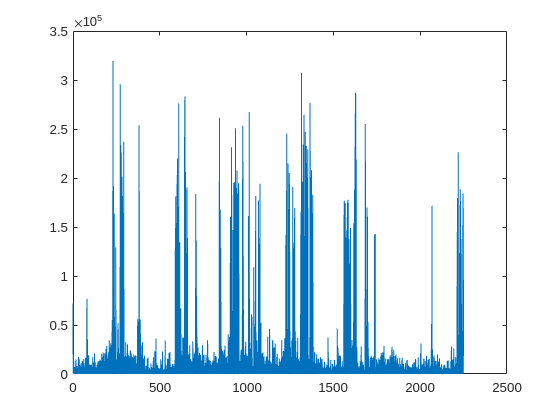

figure; plot([1:length(mot_filt)]/400,(whisk_envlope))

sigma = 0.12 * 400; % 200ms in terms of samples
smoothedEnv = imgaussfilt(whisk_envlope, sigma);

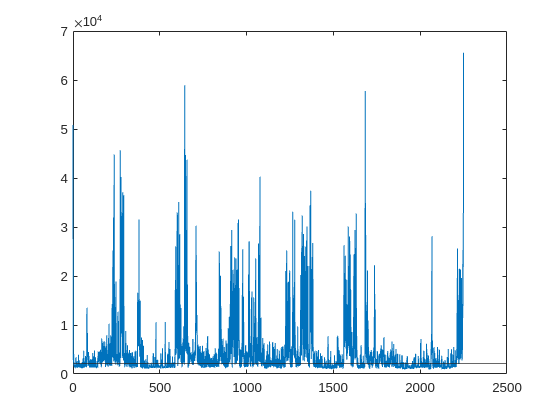

figure; plot([1:length(mot_filt)]/400,(smoothedEnv))
hold on
yline(1.5*prctile(smoothedEnv,15))

thershold = 1.5*prctile(smoothedEnv,15);
whiskingBinary = smoothedEnv > thershold;

cc = bwconncomp(whiskingBinary);

Fs = 400;

epochs = zeros(cc.NumObjects, 3); % [start, end, type]

for i = 1:cc.NumObjects
    epochs(i, 1) = cc.PixelIdxList{i}(1);   % start
    epochs(i, 2) = cc.PixelIdxList{i}(end); % end
    duration = (epochs(i, 2) - epochs(i, 1)) / Fs;
    
    if duration > 0.5 && duration <= 10
        epochs(i, 3) = 1; % Short epoch
    elseif duration > 10
        epochs(i, 3) = 2; % Long epoch
    end
end

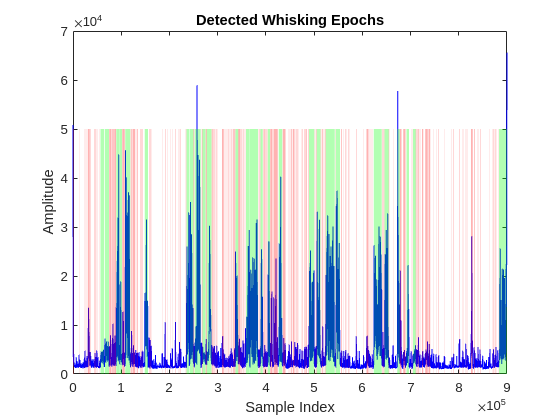

figure;
plot(smoothedEnv, 'b'); % Original signal
hold on;

for i = 1:size(epochs, 1)
    startX = epochs(i, 1);
    endX = epochs(i, 2);
    
    if epochs(i, 3) == 1
        fill([startX, endX, endX, startX], [0, 0, 50000, 50000], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    elseif epochs(i, 3) == 2
        fill([startX, endX, endX, startX], [0, 0, 50000, 50000], 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    end
end

hold off;
xlabel('Sample Index');
ylabel('Amplitude');
title('Detected Whisking Epochs');

epochsEphys = [experiment.Cams.whisking.csv_aligned_frames(epochs(1:end-1,1:2)),epochs(1:end-1,3)]

epochsEphys =         -322      176549           1
      238754      245819           0
      537818      551558           0
      554178      564306           0
      687534      687688           0
      711702      720474           0
      977890     1016089           1
     1025027     1031172           0
     1036425     1042503           0
     1078163     1086108           0



experiment.Whisking.smoothed = smoothedEnv;
experiment.Whisking.all = epochsEphys;
experiment.Whisking.short = epochsEphys(epochsEphys(:,3)==1,1:2)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB111_715'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5481×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
        

experiment.Whisking.long = epochsEphys(epochsEphys(:,3)==2,1:2)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB111_715'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5481×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
        

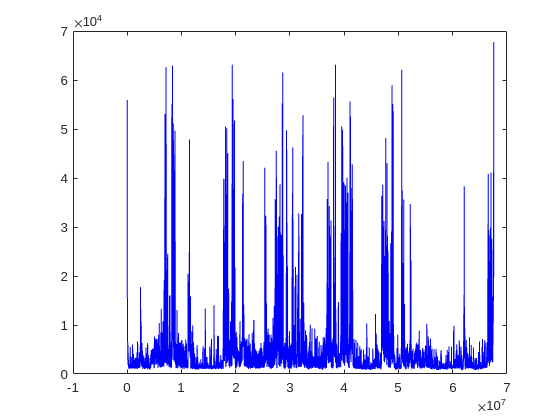

figure;
plot(experiment.Cams.whisking.csv_aligned_frames,smoothedEnv(1:length(experiment.Cams.whisking.csv_aligned_frames)), 'b'); % Original signal
hold on;


for i = 1:size(testingCond.noWhisking, 1)
    try
        startXAl = testingCond.aluminum(i, 1);
        endXAl = testingCond.aluminum(i, 2);
        fill([startXAl, endXAl, endXAl, startXAl], [0, 0, 90, 90],'r','FaceColor',colorBen.aluminum,'FaceAlpha',0.2,'EdgeColor','none');
    end
    try
        startXAt = testingCond.muted(i, 1);
        endXAt = testingCond.muted(i, 2);
        fill([startXAt, endXAt, endXAt, startXAt], [0, 0, 90, 90],'b','FaceColor',colorBen.muted, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    end
    try
        startXNo = testingCond.non(i, 1);
        endXNo = testingCond.non(i, 2);
        fill([startXNo, endXNo, endXNo, startXNo], [0, 0, 90, 90],'y','FaceColor',colorBen.non, 'FaceAlpha', 0.3, 'EdgeColor', 'none');

    end
    try
        startXNW = testingCond.noWhisking(i, 1);
        endXNW = testingCond.noWhisking(i, 2);
        fill([startXNW, endXNW, endXNW, startXNW], [0, 0, 90, 90],'y','FaceColor',colorBen.purple, 'FaceAlpha', 0.3, 'EdgeColor', 'none');

    end
end

Unable to resolve the name 'testingCond.noWhisking'.


hold off;
xlabel('Sample Index');
ylabel('Amplitude');
title('Detected Whisking Epochs');

% Divide the neurons to conditions and cross with whisking epochs
experiment.conditionVector = experiment.getConVector()

conditionV = struct with fields:
      aluminumEpochs: [15×2 int64]
         mutedEpochs: [12×2 int64]
           nonEpochs: [7×2 int64]
    noWhiskingEpochs: [657×2 int64]
            aluminum: [8855022 8855023 8855024 8855025 8855026 8855027 8855028 8855029 8855030 8855031 8855032 8855033 8855034 8855035 8855036 8855037 8855038 8855039 8855040 8855041 8855042 8855043 8855044 8855045 8855046 8855047 8855048 8855049 … ]


conditionV = struct with fields:
      aluminumEpochs: [15×2 int64]
         mutedEpochs: [12×2 int64]
           nonEpochs: [7×2 int64]
    noWhiskingEpochs: [657×2 int64]
            aluminum: [8855022 8855023 8855024 8855025 8855026 8855027 8855028 8855029 8855030 8855031 8855032 8855033 8855034 8855035 8855036 8855037 8855038 8855039 8855040 8855041 8855042 8855043 8855044 8855045 8855046 8855047 8855048 8855049 … ]
               muted: [11196809 11196810 11196811 11196812 11196813 11196814 11196815 11196816 11196817 11196818 11196819 11196820 11196821 11196822 11196823 11196824 11196825 11196826 11196827 11196828 11196829 11196830 11196831 11196832 11196833 … ]


conditionV = struct with fields:
      aluminumEpochs: [15×2 int64]
         mutedEpochs: [12×2 int64]
           nonEpochs: [7×2 int64]
    noWhiskingEpochs: [657×2 int64]
            aluminum: [8855022 8855023 8855024 8855025 8855026 8855027 8855028 8855029 8855030 8855031 8855032 8855033 8855034 8855035 8855036 8855037 8855038 8855039 8855040 8855041 8855042 8855043 8855044 8855045 8855046 8855047 8855048 8855049 … ]
               muted: [11196809 11196810 11196811 11196812 11196813 11196814 11196815 11196816 11196817 11196818 11196819 11196820 11196821 11196822 11196823 11196824 11196825 11196826 11196827 11196828 11196829 11196830 11196831 11196832 11196833 … ]
                 non: [8167510 8167511 8167512 8167513 8167514 8167515 8167516 8167517 8167518 8167519 8167520 8167521 8167522 8167523 8167524 8167525 8167526 8167527 8167528 8167529 8167530 8167531 8167532 8167533 8167534 8167535 8167536 8167537 … ]


conditionV = struct with fields:
      aluminumEpochs: [15×2 int64]
         mutedEpochs: [12×2 int64]
           nonEpochs: [7×2 int64]
    noWhiskingEpochs: [657×2 int64]
            aluminum: [8855022 8855023 8855024 8855025 8855026 8855027 8855028 8855029 8855030 8855031 8855032 8855033 8855034 8855035 8855036 8855037 8855038 8855039 8855040 8855041 8855042 8855043 8855044 8855045 8855046 8855047 8855048 8855049 … ]
               muted: [11196809 11196810 11196811 11196812 11196813 11196814 11196815 11196816 11196817 11196818 11196819 11196820 11196821 11196822 11196823 11196824 11196825 11196826 11196827 11196828 11196829 11196830 11196831 11196832 11196833 … ]
                 non: [8167510 8167511 8167512 8167513 8167514 8167515 8167516 8167517 8167518 8167519 8167520 8167521 8167522 8167523 8167524 8167525 8167526 8167527 8167528 8167529 8167530 8167531 8167532 8167533 8167534 8167535 8167536 8167537 … ]
          noWhisking: [176549 176550 176551 176552 176553 176554 176555 1

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB111_715'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5481×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
        

experiment.Units.perCondition = experiment.unitTimesCondition()

Unrecognized field name "noWhiskingCondition".

Error in auditory_ephys_exp/unitTimesCondition (line 369)
            noAttenuated_temp_good = getPerCon(obj.Units.good.times,obj.conditionVector.noWhiskingCondition.aluminum);

%experiment.Units.perCondition.FR = getFR(experiment)

Dot indexing is not supported for variables of this type.

Error in getFR (line 8)
    FR.good(unit) = length(nonzeros(experiment.Units.good.times(unit,:)))/(length(experiment.sound_events.fullSound)/30000);

allUnits = [experiment.Units.perCondition.good.alum.FR;experiment.Units.perCondition.mua.alum.FR];
allUnits(:,2) = [experiment.Units.perCondition.good.muted.FR;experiment.Units.perCondition.mua.muted.FR];
allUnits(:,3) = [experiment.Units.perCondition.good.non.FR;experiment.Units.perCondition.mua.non.FR];

allUnits = allUnits./([experiment.Units.perCondition.FR.good,experiment.Units.perCondition.FR.mua]')

allUnits =     1.1040    0.9995    0.9925
    1.0264    0.9920    0.9854
    0.9910    1.0356    1.1166
    1.0717    1.0221    1.0351
    0.8496    0.9900    1.0387
    0.8694    1.0327    1.0722
    1.0975    0.8121    0.7861
    0.8715    1.1117    1.2617
    0.9242    0.9868    0.9281
    1.4168    0.9241    0.8857


experiment.Units.perCondition.allNorm = allUnits;

%save exp 
save('FVB108_986.mat','experiment')